load"C:\Users\anand\OneDrive\Desktop\Dissertation\prog\workspace  allll.mat"
path = "C:\Users\anand\OneDrive\Desktop\Deep_learning\train"

path = "C:\Users\anand\OneDrive\Desktop\Deep_learning\train"

data = imageDatastore(path,"IncludeSubfolders",true,"LabelSource","foldernames")

data =   ImageDatastore with properties:

                       Files: {
                              ' ...\anand\OneDrive\Desktop\Deep_learning\train\baboon\n02486410_0.JPEG';
                              ' ...\anand\OneDrive\Desktop\Deep_learning\train\baboon\n02486410_1.JPEG';
                              ' ...\anand\OneDrive\Desktop\Deep_learning\train\baboon\n02486410_10.JPEG'
                               ... and 2197 more
                              }
                     Folders: {
                              'C:\Users\anand\OneDrive\Desktop\Deep_learning\train'
                              }
                      Labels: [baboon; baboon; baboon ... and 2197 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn:

data_agumented = augmentedImageDatastore([299 299 3],data,"ColorPreprocessing","gray2rgb")

data_agumented =   augmentedImageDatastore with properties:

             NumObservations: 2200
                       Files: {2200×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'gray2rgb'
                  OutputSize: [299 299]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


numClasses = numel(categories(data.Labels));

[dataTrain,dataTest] = splitEachLabel(data,0.7 , "randomized")

dataTrain =   ImageDatastore with properties:

                       Files: {
                              ' ...\anand\OneDrive\Desktop\Deep_learning\train\baboon\n02486410_10.JPEG';
                              ' ...\anand\OneDrive\Desktop\Deep_learning\train\baboon\n02486410_100.JPEG';
                              ' ...\anand\OneDrive\Desktop\Deep_learning\train\baboon\n02486410_101.JPEG'
                               ... and 1537 more
                              }
                     Folders: {
                              'C:\Users\anand\OneDrive\Desktop\Deep_learning\train'
                              }
                      Labels: [baboon; baboon; baboon ... and 1537 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                    

dataTest =   ImageDatastore with properties:

                       Files: {
                              ' ...\anand\OneDrive\Desktop\Deep_learning\train\baboon\n02486410_0.JPEG';
                              ' ...\anand\OneDrive\Desktop\Deep_learning\train\baboon\n02486410_1.JPEG';
                              ' ...\anand\OneDrive\Desktop\Deep_learning\train\baboon\n02486410_103.JPEG'
                               ... and 657 more
                              }
                     Folders: {
                              'C:\Users\anand\OneDrive\Desktop\Deep_learning\train'
                              }
                      Labels: [baboon; baboon; baboon ... and 657 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadF

Trainset = augmentedImageDatastore([299 299],dataTrain,"ColorPreprocessing","gray2rgb");
Testset = augmentedImageDatastore([299 299],dataTest,"ColorPreprocessing","gray2rgb");

# Create and Train a Deep Learning Model

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `lgraph`. The trained network is stored in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 26-Aug-2023 00:39:40

## Load Training Setup Data

Load the data used to set up training. The training setup file contains the parameters for network initialization and the training data. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

trainingSetup = load("C:\Users\anand\TrainNetworkProject1\params_2023_08_26__00_39_30.mat");

## Import Data

Import training data.

dsTrain = trainingSetup.dsTrain;

## Set Training Options

Specify options to use when training.

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.01,...
    "MaxEpochs",2,...
    "Shuffle","every-epoch",...
    "Plots","training-progress");

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([299 299 3],"Name","input_1","Normalization","rescale-symmetric","Max",trainingSetup.input_1.Max,"Min",trainingSetup.input_1.Min)
    convolution2dLayer([3 3],32,"Name","block1_conv1","BiasLearnRateFactor",0,"Stride",[2 2],"Bias",trainingSetup.block1_conv1.Bias,"Weights",trainingSetup.block1_conv1.Weights)
    batchNormalizationLayer("Name","block1_conv1_bn","Epsilon",0.001,"Offset",trainingSetup.block1_conv1_bn.Offset,"Scale",trainingSetup.block1_conv1_bn.Scale,"TrainedMean",trainingSetup.block1_conv1_bn.TrainedMean,"TrainedVariance",trainingSetup.block1_conv1_bn.TrainedVariance)
    reluLayer("Name","block1_conv1_act")
    convolution2dLayer([3 3],64,"Name","block1_conv2","BiasLearnRateFactor",0,"Bias",trainingSetup.block1_conv2.Bias,"Weights",trainingSetup.block1_conv2.Weights)
    batchNormalizationLayer("Name","block1_conv2_bn","Epsilon",0.001,"Offset",trainingSetup.block1_conv2_bn.Offset,"Scale",trainingSetup.block1_conv2_bn.Scale,"TrainedMean",trainingSetup.block1_conv2_bn.TrainedMean,"TrainedVariance",trainingSetup.block1_conv2_bn.TrainedVariance)
    reluLayer("Name","block1_conv2_act")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    groupedConvolution2dLayer([3 3],1,64,"Name","block2_sepconv1_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block2_sepconv1_channel_wise.Bias,"Weights",trainingSetup.block2_sepconv1_channel_wise.Weights)
    convolution2dLayer([1 1],128,"Name","block2_sepconv1_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block2_sepconv1_point_wise.Bias,"Weights",trainingSetup.block2_sepconv1_point_wise.Weights)
    batchNormalizationLayer("Name","block2_sepconv1_bn","Epsilon",0.001,"Offset",trainingSetup.block2_sepconv1_bn.Offset,"Scale",trainingSetup.block2_sepconv1_bn.Scale,"TrainedMean",trainingSetup.block2_sepconv1_bn.TrainedMean,"TrainedVariance",trainingSetup.block2_sepconv1_bn.TrainedVariance)
    reluLayer("Name","block2_sepconv2_act")
    groupedConvolution2dLayer([3 3],1,128,"Name","block2_sepconv2_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block2_sepconv2_channel_wise.Bias,"Weights",trainingSetup.block2_sepconv2_channel_wise.Weights)
    convolution2dLayer([1 1],128,"Name","block2_sepconv2_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block2_sepconv2_point_wise.Bias,"Weights",trainingSetup.block2_sepconv2_point_wise.Weights)
    batchNormalizationLayer("Name","block2_sepconv2_bn","Epsilon",0.001,"Offset",trainingSetup.block2_sepconv2_bn.Offset,"Scale",trainingSetup.block2_sepconv2_bn.Scale,"TrainedMean",trainingSetup.block2_sepconv2_bn.TrainedMean,"TrainedVariance",trainingSetup.block2_sepconv2_bn.TrainedVariance)
    maxPooling2dLayer([3 3],"Name","block2_pool","Padding","same","Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","conv2d_1","BiasLearnRateFactor",0,"Padding","same","Stride",[2 2],"Bias",trainingSetup.conv2d_1.Bias,"Weights",trainingSetup.conv2d_1.Weights)
    batchNormalizationLayer("Name","batch_normalization_1","Epsilon",0.001,"Offset",trainingSetup.batch_normalization_1.Offset,"Scale",trainingSetup.batch_normalization_1.Scale,"TrainedMean",trainingSetup.batch_normalization_1.TrainedMean,"TrainedVariance",trainingSetup.batch_normalization_1.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","add_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    reluLayer("Name","block3_sepconv1_act")
    groupedConvolution2dLayer([3 3],1,128,"Name","block3_sepconv1_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block3_sepconv1_channel_wise.Bias,"Weights",trainingSetup.block3_sepconv1_channel_wise.Weights)
    convolution2dLayer([1 1],256,"Name","block3_sepconv1_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block3_sepconv1_point_wise.Bias,"Weights",trainingSetup.block3_sepconv1_point_wise.Weights)
    batchNormalizationLayer("Name","block3_sepconv1_bn","Epsilon",0.001,"Offset",trainingSetup.block3_sepconv1_bn.Offset,"Scale",trainingSetup.block3_sepconv1_bn.Scale,"TrainedMean",trainingSetup.block3_sepconv1_bn.TrainedMean,"TrainedVariance",trainingSetup.block3_sepconv1_bn.TrainedVariance)
    reluLayer("Name","block3_sepconv2_act")
    groupedConvolution2dLayer([3 3],1,256,"Name","block3_sepconv2_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block3_sepconv2_channel_wise.Bias,"Weights",trainingSetup.block3_sepconv2_channel_wise.Weights)
    convolution2dLayer([1 1],256,"Name","block3_sepconv2_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block3_sepconv2_point_wise.Bias,"Weights",trainingSetup.block3_sepconv2_point_wise.Weights)
    batchNormalizationLayer("Name","block3_sepconv2_bn","Epsilon",0.001,"Offset",trainingSetup.block3_sepconv2_bn.Offset,"Scale",trainingSetup.block3_sepconv2_bn.Scale,"TrainedMean",trainingSetup.block3_sepconv2_bn.TrainedMean,"TrainedVariance",trainingSetup.block3_sepconv2_bn.TrainedVariance)
    maxPooling2dLayer([3 3],"Name","block3_pool","Padding","same","Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","conv2d_2","BiasLearnRateFactor",0,"Padding","same","Stride",[2 2],"Bias",trainingSetup.conv2d_2.Bias,"Weights",trainingSetup.conv2d_2.Weights)
    batchNormalizationLayer("Name","batch_normalization_2","Epsilon",0.001,"Offset",trainingSetup.batch_normalization_2.Offset,"Scale",trainingSetup.batch_normalization_2.Scale,"TrainedMean",trainingSetup.batch_normalization_2.TrainedMean,"TrainedVariance",trainingSetup.batch_normalization_2.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","add_2");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    reluLayer("Name","block4_sepconv1_act")
    groupedConvolution2dLayer([3 3],1,256,"Name","block4_sepconv1_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block4_sepconv1_channel_wise.Bias,"Weights",trainingSetup.block4_sepconv1_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block4_sepconv1_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block4_sepconv1_point_wise.Bias,"Weights",trainingSetup.block4_sepconv1_point_wise.Weights)
    batchNormalizationLayer("Name","block4_sepconv1_bn","Epsilon",0.001,"Offset",trainingSetup.block4_sepconv1_bn.Offset,"Scale",trainingSetup.block4_sepconv1_bn.Scale,"TrainedMean",trainingSetup.block4_sepconv1_bn.TrainedMean,"TrainedVariance",trainingSetup.block4_sepconv1_bn.TrainedVariance)
    reluLayer("Name","block4_sepconv2_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block4_sepconv2_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block4_sepconv2_channel_wise.Bias,"Weights",trainingSetup.block4_sepconv2_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block4_sepconv2_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block4_sepconv2_point_wise.Bias,"Weights",trainingSetup.block4_sepconv2_point_wise.Weights)
    batchNormalizationLayer("Name","block4_sepconv2_bn","Epsilon",0.001,"Offset",trainingSetup.block4_sepconv2_bn.Offset,"Scale",trainingSetup.block4_sepconv2_bn.Scale,"TrainedMean",trainingSetup.block4_sepconv2_bn.TrainedMean,"TrainedVariance",trainingSetup.block4_sepconv2_bn.TrainedVariance)
    maxPooling2dLayer([3 3],"Name","block4_pool","Padding","same","Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],728,"Name","conv2d_3","BiasLearnRateFactor",0,"Padding","same","Stride",[2 2],"Bias",trainingSetup.conv2d_3.Bias,"Weights",trainingSetup.conv2d_3.Weights)
    batchNormalizationLayer("Name","batch_normalization_3","Epsilon",0.001,"Offset",trainingSetup.batch_normalization_3.Offset,"Scale",trainingSetup.batch_normalization_3.Scale,"TrainedMean",trainingSetup.batch_normalization_3.TrainedMean,"TrainedVariance",trainingSetup.batch_normalization_3.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","add_3");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    reluLayer("Name","block5_sepconv1_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block5_sepconv1_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block5_sepconv1_channel_wise.Bias,"Weights",trainingSetup.block5_sepconv1_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block5_sepconv1_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block5_sepconv1_point_wise.Bias,"Weights",trainingSetup.block5_sepconv1_point_wise.Weights)
    batchNormalizationLayer("Name","block5_sepconv1_bn","Epsilon",0.001,"Offset",trainingSetup.block5_sepconv1_bn.Offset,"Scale",trainingSetup.block5_sepconv1_bn.Scale,"TrainedMean",trainingSetup.block5_sepconv1_bn.TrainedMean,"TrainedVariance",trainingSetup.block5_sepconv1_bn.TrainedVariance)
    reluLayer("Name","block5_sepconv2_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block5_sepconv2_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block5_sepconv2_channel_wise.Bias,"Weights",trainingSetup.block5_sepconv2_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block5_sepconv2_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block5_sepconv2_point_wise.Bias,"Weights",trainingSetup.block5_sepconv2_point_wise.Weights)
    batchNormalizationLayer("Name","block5_sepconv2_bn","Epsilon",0.001,"Offset",trainingSetup.block5_sepconv2_bn.Offset,"Scale",trainingSetup.block5_sepconv2_bn.Scale,"TrainedMean",trainingSetup.block5_sepconv2_bn.TrainedMean,"TrainedVariance",trainingSetup.block5_sepconv2_bn.TrainedVariance)
    reluLayer("Name","block5_sepconv3_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block5_sepconv3_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block5_sepconv3_channel_wise.Bias,"Weights",trainingSetup.block5_sepconv3_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block5_sepconv3_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block5_sepconv3_point_wise.Bias,"Weights",trainingSetup.block5_sepconv3_point_wise.Weights)
    batchNormalizationLayer("Name","block5_sepconv3_bn","Epsilon",0.001,"Offset",trainingSetup.block5_sepconv3_bn.Offset,"Scale",trainingSetup.block5_sepconv3_bn.Scale,"TrainedMean",trainingSetup.block5_sepconv3_bn.TrainedMean,"TrainedVariance",trainingSetup.block5_sepconv3_bn.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","add_4");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    reluLayer("Name","block6_sepconv1_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block6_sepconv1_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block6_sepconv1_channel_wise.Bias,"Weights",trainingSetup.block6_sepconv1_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block6_sepconv1_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block6_sepconv1_point_wise.Bias,"Weights",trainingSetup.block6_sepconv1_point_wise.Weights)
    batchNormalizationLayer("Name","block6_sepconv1_bn","Epsilon",0.001,"Offset",trainingSetup.block6_sepconv1_bn.Offset,"Scale",trainingSetup.block6_sepconv1_bn.Scale,"TrainedMean",trainingSetup.block6_sepconv1_bn.TrainedMean,"TrainedVariance",trainingSetup.block6_sepconv1_bn.TrainedVariance)
    reluLayer("Name","block6_sepconv2_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block6_sepconv2_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block6_sepconv2_channel_wise.Bias,"Weights",trainingSetup.block6_sepconv2_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block6_sepconv2_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block6_sepconv2_point_wise.Bias,"Weights",trainingSetup.block6_sepconv2_point_wise.Weights)
    batchNormalizationLayer("Name","block6_sepconv2_bn","Epsilon",0.001,"Offset",trainingSetup.block6_sepconv2_bn.Offset,"Scale",trainingSetup.block6_sepconv2_bn.Scale,"TrainedMean",trainingSetup.block6_sepconv2_bn.TrainedMean,"TrainedVariance",trainingSetup.block6_sepconv2_bn.TrainedVariance)
    reluLayer("Name","block6_sepconv3_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block6_sepconv3_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block6_sepconv3_channel_wise.Bias,"Weights",trainingSetup.block6_sepconv3_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block6_sepconv3_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block6_sepconv3_point_wise.Bias,"Weights",trainingSetup.block6_sepconv3_point_wise.Weights)
    batchNormalizationLayer("Name","block6_sepconv3_bn","Epsilon",0.001,"Offset",trainingSetup.block6_sepconv3_bn.Offset,"Scale",trainingSetup.block6_sepconv3_bn.Scale,"TrainedMean",trainingSetup.block6_sepconv3_bn.TrainedMean,"TrainedVariance",trainingSetup.block6_sepconv3_bn.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","add_5");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    reluLayer("Name","block7_sepconv1_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block7_sepconv1_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block7_sepconv1_channel_wise.Bias,"Weights",trainingSetup.block7_sepconv1_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block7_sepconv1_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block7_sepconv1_point_wise.Bias,"Weights",trainingSetup.block7_sepconv1_point_wise.Weights)
    batchNormalizationLayer("Name","block7_sepconv1_bn","Epsilon",0.001,"Offset",trainingSetup.block7_sepconv1_bn.Offset,"Scale",trainingSetup.block7_sepconv1_bn.Scale,"TrainedMean",trainingSetup.block7_sepconv1_bn.TrainedMean,"TrainedVariance",trainingSetup.block7_sepconv1_bn.TrainedVariance)
    reluLayer("Name","block7_sepconv2_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block7_sepconv2_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block7_sepconv2_channel_wise.Bias,"Weights",trainingSetup.block7_sepconv2_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block7_sepconv2_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block7_sepconv2_point_wise.Bias,"Weights",trainingSetup.block7_sepconv2_point_wise.Weights)
    batchNormalizationLayer("Name","block7_sepconv2_bn","Epsilon",0.001,"Offset",trainingSetup.block7_sepconv2_bn.Offset,"Scale",trainingSetup.block7_sepconv2_bn.Scale,"TrainedMean",trainingSetup.block7_sepconv2_bn.TrainedMean,"TrainedVariance",trainingSetup.block7_sepconv2_bn.TrainedVariance)
    reluLayer("Name","block7_sepconv3_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block7_sepconv3_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block7_sepconv3_channel_wise.Bias,"Weights",trainingSetup.block7_sepconv3_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block7_sepconv3_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block7_sepconv3_point_wise.Bias,"Weights",trainingSetup.block7_sepconv3_point_wise.Weights)
    batchNormalizationLayer("Name","block7_sepconv3_bn","Epsilon",0.001,"Offset",trainingSetup.block7_sepconv3_bn.Offset,"Scale",trainingSetup.block7_sepconv3_bn.Scale,"TrainedMean",trainingSetup.block7_sepconv3_bn.TrainedMean,"TrainedVariance",trainingSetup.block7_sepconv3_bn.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","add_6");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    reluLayer("Name","block8_sepconv1_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block8_sepconv1_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block8_sepconv1_channel_wise.Bias,"Weights",trainingSetup.block8_sepconv1_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block8_sepconv1_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block8_sepconv1_point_wise.Bias,"Weights",trainingSetup.block8_sepconv1_point_wise.Weights)
    batchNormalizationLayer("Name","block8_sepconv1_bn","Epsilon",0.001,"Offset",trainingSetup.block8_sepconv1_bn.Offset,"Scale",trainingSetup.block8_sepconv1_bn.Scale,"TrainedMean",trainingSetup.block8_sepconv1_bn.TrainedMean,"TrainedVariance",trainingSetup.block8_sepconv1_bn.TrainedVariance)
    reluLayer("Name","block8_sepconv2_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block8_sepconv2_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block8_sepconv2_channel_wise.Bias,"Weights",trainingSetup.block8_sepconv2_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block8_sepconv2_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block8_sepconv2_point_wise.Bias,"Weights",trainingSetup.block8_sepconv2_point_wise.Weights)
    batchNormalizationLayer("Name","block8_sepconv2_bn","Epsilon",0.001,"Offset",trainingSetup.block8_sepconv2_bn.Offset,"Scale",trainingSetup.block8_sepconv2_bn.Scale,"TrainedMean",trainingSetup.block8_sepconv2_bn.TrainedMean,"TrainedVariance",trainingSetup.block8_sepconv2_bn.TrainedVariance)
    reluLayer("Name","block8_sepconv3_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block8_sepconv3_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block8_sepconv3_channel_wise.Bias,"Weights",trainingSetup.block8_sepconv3_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block8_sepconv3_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block8_sepconv3_point_wise.Bias,"Weights",trainingSetup.block8_sepconv3_point_wise.Weights)
    batchNormalizationLayer("Name","block8_sepconv3_bn","Epsilon",0.001,"Offset",trainingSetup.block8_sepconv3_bn.Offset,"Scale",trainingSetup.block8_sepconv3_bn.Scale,"TrainedMean",trainingSetup.block8_sepconv3_bn.TrainedMean,"TrainedVariance",trainingSetup.block8_sepconv3_bn.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","add_7");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    reluLayer("Name","block9_sepconv1_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block9_sepconv1_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block9_sepconv1_channel_wise.Bias,"Weights",trainingSetup.block9_sepconv1_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block9_sepconv1_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block9_sepconv1_point_wise.Bias,"Weights",trainingSetup.block9_sepconv1_point_wise.Weights)
    batchNormalizationLayer("Name","block9_sepconv1_bn","Epsilon",0.001,"Offset",trainingSetup.block9_sepconv1_bn.Offset,"Scale",trainingSetup.block9_sepconv1_bn.Scale,"TrainedMean",trainingSetup.block9_sepconv1_bn.TrainedMean,"TrainedVariance",trainingSetup.block9_sepconv1_bn.TrainedVariance)
    reluLayer("Name","block9_sepconv2_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block9_sepconv2_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block9_sepconv2_channel_wise.Bias,"Weights",trainingSetup.block9_sepconv2_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block9_sepconv2_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block9_sepconv2_point_wise.Bias,"Weights",trainingSetup.block9_sepconv2_point_wise.Weights)
    batchNormalizationLayer("Name","block9_sepconv2_bn","Epsilon",0.001,"Offset",trainingSetup.block9_sepconv2_bn.Offset,"Scale",trainingSetup.block9_sepconv2_bn.Scale,"TrainedMean",trainingSetup.block9_sepconv2_bn.TrainedMean,"TrainedVariance",trainingSetup.block9_sepconv2_bn.TrainedVariance)
    reluLayer("Name","block9_sepconv3_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block9_sepconv3_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block9_sepconv3_channel_wise.Bias,"Weights",trainingSetup.block9_sepconv3_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block9_sepconv3_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block9_sepconv3_point_wise.Bias,"Weights",trainingSetup.block9_sepconv3_point_wise.Weights)
    batchNormalizationLayer("Name","block9_sepconv3_bn","Epsilon",0.001,"Offset",trainingSetup.block9_sepconv3_bn.Offset,"Scale",trainingSetup.block9_sepconv3_bn.Scale,"TrainedMean",trainingSetup.block9_sepconv3_bn.TrainedMean,"TrainedVariance",trainingSetup.block9_sepconv3_bn.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","add_8");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    reluLayer("Name","block10_sepconv1_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block10_sepconv1_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block10_sepconv1_channel_wise.Bias,"Weights",trainingSetup.block10_sepconv1_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block10_sepconv1_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block10_sepconv1_point_wise.Bias,"Weights",trainingSetup.block10_sepconv1_point_wise.Weights)
    batchNormalizationLayer("Name","block10_sepconv1_bn","Epsilon",0.001,"Offset",trainingSetup.block10_sepconv1_bn.Offset,"Scale",trainingSetup.block10_sepconv1_bn.Scale,"TrainedMean",trainingSetup.block10_sepconv1_bn.TrainedMean,"TrainedVariance",trainingSetup.block10_sepconv1_bn.TrainedVariance)
    reluLayer("Name","block10_sepconv2_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block10_sepconv2_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block10_sepconv2_channel_wise.Bias,"Weights",trainingSetup.block10_sepconv2_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block10_sepconv2_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block10_sepconv2_point_wise.Bias,"Weights",trainingSetup.block10_sepconv2_point_wise.Weights)
    batchNormalizationLayer("Name","block10_sepconv2_bn","Epsilon",0.001,"Offset",trainingSetup.block10_sepconv2_bn.Offset,"Scale",trainingSetup.block10_sepconv2_bn.Scale,"TrainedMean",trainingSetup.block10_sepconv2_bn.TrainedMean,"TrainedVariance",trainingSetup.block10_sepconv2_bn.TrainedVariance)
    reluLayer("Name","block10_sepconv3_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block10_sepconv3_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block10_sepconv3_channel_wise.Bias,"Weights",trainingSetup.block10_sepconv3_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block10_sepconv3_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block10_sepconv3_point_wise.Bias,"Weights",trainingSetup.block10_sepconv3_point_wise.Weights)
    batchNormalizationLayer("Name","block10_sepconv3_bn","Epsilon",0.001,"Offset",trainingSetup.block10_sepconv3_bn.Offset,"Scale",trainingSetup.block10_sepconv3_bn.Scale,"TrainedMean",trainingSetup.block10_sepconv3_bn.TrainedMean,"TrainedVariance",trainingSetup.block10_sepconv3_bn.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","add_9");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    reluLayer("Name","block11_sepconv1_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block11_sepconv1_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block11_sepconv1_channel_wise.Bias,"Weights",trainingSetup.block11_sepconv1_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block11_sepconv1_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block11_sepconv1_point_wise.Bias,"Weights",trainingSetup.block11_sepconv1_point_wise.Weights)
    batchNormalizationLayer("Name","block11_sepconv1_bn","Epsilon",0.001,"Offset",trainingSetup.block11_sepconv1_bn.Offset,"Scale",trainingSetup.block11_sepconv1_bn.Scale,"TrainedMean",trainingSetup.block11_sepconv1_bn.TrainedMean,"TrainedVariance",trainingSetup.block11_sepconv1_bn.TrainedVariance)
    reluLayer("Name","block11_sepconv2_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block11_sepconv2_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block11_sepconv2_channel_wise.Bias,"Weights",trainingSetup.block11_sepconv2_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block11_sepconv2_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block11_sepconv2_point_wise.Bias,"Weights",trainingSetup.block11_sepconv2_point_wise.Weights)
    batchNormalizationLayer("Name","block11_sepconv2_bn","Epsilon",0.001,"Offset",trainingSetup.block11_sepconv2_bn.Offset,"Scale",trainingSetup.block11_sepconv2_bn.Scale,"TrainedMean",trainingSetup.block11_sepconv2_bn.TrainedMean,"TrainedVariance",trainingSetup.block11_sepconv2_bn.TrainedVariance)
    reluLayer("Name","block11_sepconv3_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block11_sepconv3_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block11_sepconv3_channel_wise.Bias,"Weights",trainingSetup.block11_sepconv3_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block11_sepconv3_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block11_sepconv3_point_wise.Bias,"Weights",trainingSetup.block11_sepconv3_point_wise.Weights)
    batchNormalizationLayer("Name","block11_sepconv3_bn","Epsilon",0.001,"Offset",trainingSetup.block11_sepconv3_bn.Offset,"Scale",trainingSetup.block11_sepconv3_bn.Scale,"TrainedMean",trainingSetup.block11_sepconv3_bn.TrainedMean,"TrainedVariance",trainingSetup.block11_sepconv3_bn.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","add_10");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    reluLayer("Name","block12_sepconv1_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block12_sepconv1_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block12_sepconv1_channel_wise.Bias,"Weights",trainingSetup.block12_sepconv1_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block12_sepconv1_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block12_sepconv1_point_wise.Bias,"Weights",trainingSetup.block12_sepconv1_point_wise.Weights)
    batchNormalizationLayer("Name","block12_sepconv1_bn","Epsilon",0.001,"Offset",trainingSetup.block12_sepconv1_bn.Offset,"Scale",trainingSetup.block12_sepconv1_bn.Scale,"TrainedMean",trainingSetup.block12_sepconv1_bn.TrainedMean,"TrainedVariance",trainingSetup.block12_sepconv1_bn.TrainedVariance)
    reluLayer("Name","block12_sepconv2_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block12_sepconv2_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block12_sepconv2_channel_wise.Bias,"Weights",trainingSetup.block12_sepconv2_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block12_sepconv2_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block12_sepconv2_point_wise.Bias,"Weights",trainingSetup.block12_sepconv2_point_wise.Weights)
    batchNormalizationLayer("Name","block12_sepconv2_bn","Epsilon",0.001,"Offset",trainingSetup.block12_sepconv2_bn.Offset,"Scale",trainingSetup.block12_sepconv2_bn.Scale,"TrainedMean",trainingSetup.block12_sepconv2_bn.TrainedMean,"TrainedVariance",trainingSetup.block12_sepconv2_bn.TrainedVariance)
    reluLayer("Name","block12_sepconv3_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block12_sepconv3_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block12_sepconv3_channel_wise.Bias,"Weights",trainingSetup.block12_sepconv3_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block12_sepconv3_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block12_sepconv3_point_wise.Bias,"Weights",trainingSetup.block12_sepconv3_point_wise.Weights)
    batchNormalizationLayer("Name","block12_sepconv3_bn","Epsilon",0.001,"Offset",trainingSetup.block12_sepconv3_bn.Offset,"Scale",trainingSetup.block12_sepconv3_bn.Scale,"TrainedMean",trainingSetup.block12_sepconv3_bn.TrainedMean,"TrainedVariance",trainingSetup.block12_sepconv3_bn.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","add_11");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    reluLayer("Name","block13_sepconv1_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block13_sepconv1_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block13_sepconv1_channel_wise.Bias,"Weights",trainingSetup.block13_sepconv1_channel_wise.Weights)
    convolution2dLayer([1 1],728,"Name","block13_sepconv1_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block13_sepconv1_point_wise.Bias,"Weights",trainingSetup.block13_sepconv1_point_wise.Weights)
    batchNormalizationLayer("Name","block13_sepconv1_bn","Epsilon",0.001,"Offset",trainingSetup.block13_sepconv1_bn.Offset,"Scale",trainingSetup.block13_sepconv1_bn.Scale,"TrainedMean",trainingSetup.block13_sepconv1_bn.TrainedMean,"TrainedVariance",trainingSetup.block13_sepconv1_bn.TrainedVariance)
    reluLayer("Name","block13_sepconv2_act")
    groupedConvolution2dLayer([3 3],1,728,"Name","block13_sepconv2_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block13_sepconv2_channel_wise.Bias,"Weights",trainingSetup.block13_sepconv2_channel_wise.Weights)
    convolution2dLayer([1 1],1024,"Name","block13_sepconv2_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block13_sepconv2_point_wise.Bias,"Weights",trainingSetup.block13_sepconv2_point_wise.Weights)
    batchNormalizationLayer("Name","block13_sepconv2_bn","Epsilon",0.001,"Offset",trainingSetup.block13_sepconv2_bn.Offset,"Scale",trainingSetup.block13_sepconv2_bn.Scale,"TrainedMean",trainingSetup.block13_sepconv2_bn.TrainedMean,"TrainedVariance",trainingSetup.block13_sepconv2_bn.TrainedVariance)
    maxPooling2dLayer([3 3],"Name","block13_pool","Padding","same","Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],1024,"Name","conv2d_4","BiasLearnRateFactor",0,"Padding","same","Stride",[2 2],"Bias",trainingSetup.conv2d_4.Bias,"Weights",trainingSetup.conv2d_4.Weights)
    batchNormalizationLayer("Name","batch_normalization_4","Epsilon",0.001,"Offset",trainingSetup.batch_normalization_4.Offset,"Scale",trainingSetup.batch_normalization_4.Scale,"TrainedMean",trainingSetup.batch_normalization_4.TrainedMean,"TrainedVariance",trainingSetup.batch_normalization_4.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_12")
    groupedConvolution2dLayer([3 3],1,1024,"Name","block14_sepconv1_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block14_sepconv1_channel_wise.Bias,"Weights",trainingSetup.block14_sepconv1_channel_wise.Weights)
    convolution2dLayer([1 1],1536,"Name","block14_sepconv1_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block14_sepconv1_point_wise.Bias,"Weights",trainingSetup.block14_sepconv1_point_wise.Weights)
    batchNormalizationLayer("Name","block14_sepconv1_bn","Epsilon",0.001,"Offset",trainingSetup.block14_sepconv1_bn.Offset,"Scale",trainingSetup.block14_sepconv1_bn.Scale,"TrainedMean",trainingSetup.block14_sepconv1_bn.TrainedMean,"TrainedVariance",trainingSetup.block14_sepconv1_bn.TrainedVariance)
    reluLayer("Name","block14_sepconv1_act")
    groupedConvolution2dLayer([3 3],1,1536,"Name","block14_sepconv2_channel-wise","BiasLearnRateFactor",0,"Padding","same","Bias",trainingSetup.block14_sepconv2_channel_wise.Bias,"Weights",trainingSetup.block14_sepconv2_channel_wise.Weights)
    convolution2dLayer([1 1],2048,"Name","block14_sepconv2_point-wise","BiasLearnRateFactor",0,"Bias",trainingSetup.block14_sepconv2_point_wise.Bias,"Weights",trainingSetup.block14_sepconv2_point_wise.Weights)
    batchNormalizationLayer("Name","block14_sepconv2_bn","Epsilon",0.001,"Offset",trainingSetup.block14_sepconv2_bn.Offset,"Scale",trainingSetup.block14_sepconv2_bn.Scale,"TrainedMean",trainingSetup.block14_sepconv2_bn.TrainedMean,"TrainedVariance",trainingSetup.block14_sepconv2_bn.TrainedVariance)
    reluLayer("Name","block14_sepconv2_act")
    globalAveragePooling2dLayer("Name","avg_pool")
    fullyConnectedLayer(5,"Name","fc")
    softmaxLayer("Name","predictions_softmax")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"block1_conv2_act","block2_sepconv1_channel-wise");
lgraph = connectLayers(lgraph,"block1_conv2_act","conv2d_1");
lgraph = connectLayers(lgraph,"batch_normalization_1","add_1/in2");
lgraph = connectLayers(lgraph,"block2_pool","add_1/in1");
lgraph = connectLayers(lgraph,"add_1","block3_sepconv1_act");
lgraph = connectLayers(lgraph,"add_1","conv2d_2");
lgraph = connectLayers(lgraph,"batch_normalization_2","add_2/in2");
lgraph = connectLayers(lgraph,"block3_pool","add_2/in1");
lgraph = connectLayers(lgraph,"add_2","block4_sepconv1_act");
lgraph = connectLayers(lgraph,"add_2","conv2d_3");
lgraph = connectLayers(lgraph,"batch_normalization_3","add_3/in2");
lgraph = connectLayers(lgraph,"block4_pool","add_3/in1");
lgraph = connectLayers(lgraph,"add_3","block5_sepconv1_act");
lgraph = connectLayers(lgraph,"add_3","add_4/in2");
lgraph = connectLayers(lgraph,"block5_sepconv3_bn","add_4/in1");
lgraph = connectLayers(lgraph,"add_4","block6_sepconv1_act");
lgraph = connectLayers(lgraph,"add_4","add_5/in2");
lgraph = connectLayers(lgraph,"block6_sepconv3_bn","add_5/in1");
lgraph = connectLayers(lgraph,"add_5","block7_sepconv1_act");
lgraph = connectLayers(lgraph,"add_5","add_6/in2");
lgraph = connectLayers(lgraph,"block7_sepconv3_bn","add_6/in1");
lgraph = connectLayers(lgraph,"add_6","block8_sepconv1_act");
lgraph = connectLayers(lgraph,"add_6","add_7/in2");
lgraph = connectLayers(lgraph,"block8_sepconv3_bn","add_7/in1");
lgraph = connectLayers(lgraph,"add_7","block9_sepconv1_act");
lgraph = connectLayers(lgraph,"add_7","add_8/in2");
lgraph = connectLayers(lgraph,"block9_sepconv3_bn","add_8/in1");
lgraph = connectLayers(lgraph,"add_8","block10_sepconv1_act");
lgraph = connectLayers(lgraph,"add_8","add_9/in2");
lgraph = connectLayers(lgraph,"block10_sepconv3_bn","add_9/in1");
lgraph = connectLayers(lgraph,"add_9","block11_sepconv1_act");
lgraph = connectLayers(lgraph,"add_9","add_10/in2");
lgraph = connectLayers(lgraph,"block11_sepconv3_bn","add_10/in1");
lgraph = connectLayers(lgraph,"add_10","block12_sepconv1_act");
lgraph = connectLayers(lgraph,"add_10","add_11/in2");
lgraph = connectLayers(lgraph,"block12_sepconv3_bn","add_11/in1");
lgraph = connectLayers(lgraph,"add_11","block13_sepconv1_act");
lgraph = connectLayers(lgraph,"add_11","conv2d_4");
lgraph = connectLayers(lgraph,"batch_normalization_4","add_12/in2");
lgraph = connectLayers(lgraph,"block13_pool","add_12/in1");

## Train Network

Train the network using the specified options and training data.

[net, traininfo] = trainNetwork(dsTrain,lgraph,opts);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


Actual = dataTest.Labels;
predictions_2  = classify(trainedNetwork_3,Testset)
numCorrect_2 = nnz(predictions_2 == Actual)


fracCorrect_2 = numCorrect_2/numel(predictions_2)
confusionchart(Actual,predictions_2)

% Assuming C is your confusion matrix
C = confusionmat(Actual,predictions_2);

% Total number of classifications
total = sum(sum(C));

% True Positive
TP = diag(C);

% False Positive
FP = sum(C, 1)' - TP;

% False Negative
FN = sum(C, 2) - TP;

% True Negative
TN = total - FP - FN - TP;

% Accuracy
accuracy = sum(TP) / total;

% Precision, Recall, and F1-score for each class
precision = TP ./ (TP + FP);
recall = TP ./ (TP + FN);
f1_score = 2 * (precision .* recall) ./ (precision + recall);

% Display the results
disp(['Accuracy: ', num2str(accuracy)]);
disp('Precision:'); disp(precision);
disp('Recall:'); disp(recall);
disp('F1-Score:'); disp(f1_score);


net = trainedNetwork_3;
lgraph = layerGraph(net);
lgraph = removeLayers(lgraph,lgraph.Layers(end).Name);
dlnet = dlnetwork(lgraph);

Extract the class labels.

classes = categories(net.Layers(end).Classes)

classes = 5×1 cell array
    {'baboon'   }
    {'candle'   }
    {'cats'     }
    {'dogs'     }
    {'hourglass'}


sherlock = "C:\Users\anand\OneDrive\Desktop\sherlock.jpg"

sherlock = "C:\Users\anand\OneDrive\Desktop\sherlock.jpg"


img = imread(sherlock);
inputSize = trainedNetwork_1.Layers(1).InputSize;
img = imresize(img,inputSize(1:2));


classes = categories(trainedNetwork_1.Layers(end).Classes)

classes = 5×1 cell array
    {'baboon'   }
    {'candle'   }
    {'cats'     }
    {'dogs'     }
    {'hourglass'}


Actual = dataTest.Labels;
predictions  = classify(trainedNetwork_3,Testset)

predictions = 660×1 categorical array
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 
     baboon 


numCorrect = nnz(predictions == Actual)

numCorrect = 646


fracCorrect = numCorrect/numel(predictions)

fracCorrect = 0.9788

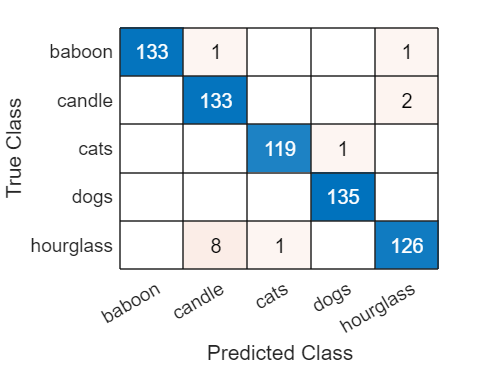

confusionchart(Actual,predictions)

C = confusionmat(Actual,predictions)

C =    133     1     0     0     1
     0   133     0     0     2
     0     0   119     1     0
     0     0     0   135     0
     0     8     1     0   126



% Total number of classifications
total = sum(sum(C));

% True Positive
TP = diag(C);

% False Positive
FP = sum(C, 1)' - TP;

% False Negative
FN = sum(C, 2) - TP;

% True Negative
TN = total - FP - FN - TP;

% Accuracy
accuracy = sum(TP) / total;

% Precision, Recall, and F1-score for each class
precision = TP ./ (TP + FP);
recall = TP ./ (TP + FN);
f1_score = 2 * (precision .* recall) ./ (precision + recall);

% Display the results
disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 0.97879


disp('Precision:'); disp(precision);

Precision:
    1.0000
    0.9366
    0.9917
    0.9926
    0.9767



disp('Recall:'); disp(recall)

Recall:
    0.9852
    0.9852
    0.9917
    1.0000
    0.9333



disp('F1-Score:'); disp(f1_score)

F1-Score:
    0.9925
    0.9603
    0.9917
    0.9963
    0.9545



sherlock = "C:\Users\anand\OneDrive\Desktop\sherlock.jpg"

sherlock = "C:\Users\anand\OneDrive\Desktop\sherlock.jpg"

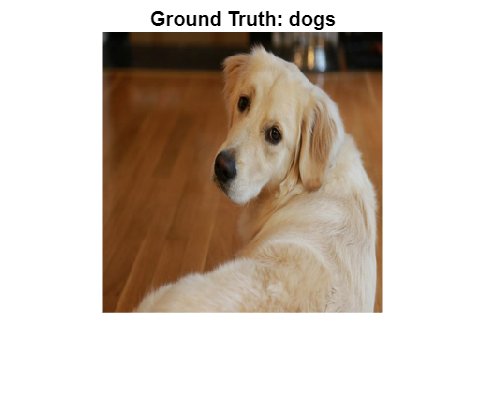

img = imread(sherlock);
T = "dogs";inputSize = dlnet.Layers(1).InputSize;
img = imresize(img,inputSize(1:2));

figure
imshow(img)
title("Ground Truth: " + T)

Prepare the image by converting it to a `dlarray`.

X = dlarray(single(img),"SSCB");

Prepare the label by one-hot encoding it.

T = onehotencode(T,1,'ClassNames',classes);
T = dlarray(single(T),"CB");gradient = dlfeval(@untargetedGradients,dlnet,X,T);
epsilon = 100;
XAdv = X + epsilon*sign(gradient);

Predict the class of the original image and the adversarial image.

YPred = predict(dlnet,X);
YPred = onehotdecode(squeeze(YPred),classes,1)

YPred = categorical
     dogs 


YPredAdv = predict(dlnet,XAdv);
YPredAdv = onehotdecode(squeeze(YPredAdv),classes,1)

YPredAdv = categorical
     dogs 


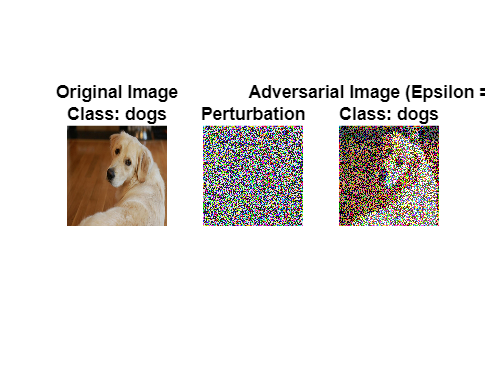

showAdversarialImage(X,YPred,XAdv,YPredAdv,epsilon);

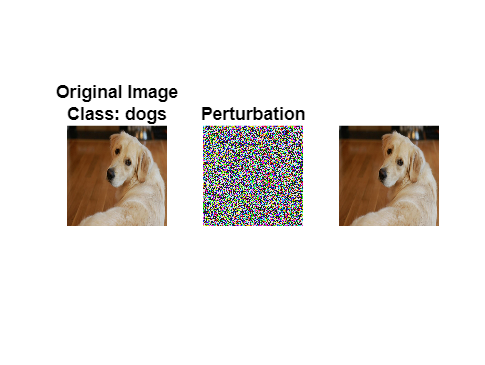

[pppp,scores] = classify(trainedNetwork_3,img);
[~,topIdx] = maxk(scores, 5);
topScores = scores(topIdx);
topClasses = classes(topIdx);

imshow(img)

topClasses

topClasses = 5×1 cell array
    {'dogs'     }
    {'cats'     }
    {'candle'   }
    {'hourglass'}
    {'baboon'   }


topScores

topScores = 1×5 single row vector
    0.9325    0.0233    0.0213    0.0139    0.0089


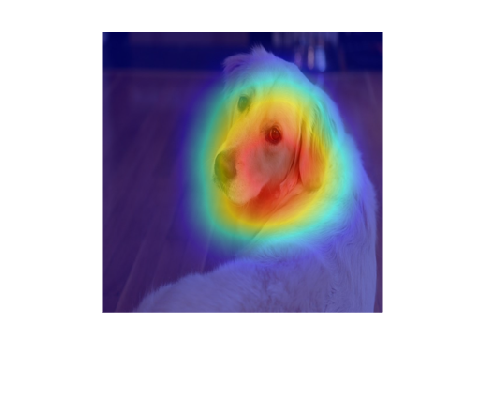

scoreMap = gradCAM(net,X,YPred);
gradimg = uint8(extractdata(X));
figure
imshow(gradimg)

hold on
imagesc(scoreMap,'AlphaData',0.5)
colormap jet

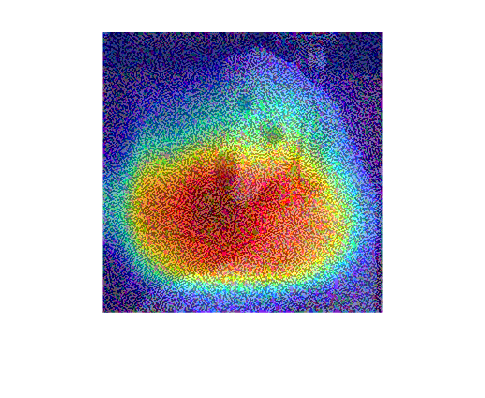



scoreMap1 = gradCAM(net,XAdv,YPredAdv);
gradimg1 = uint8(extractdata(XAdv));
figure
imshow(gradimg1)

hold on
imagesc(scoreMap1,'AlphaData',0.5)
colormap jet

function gradient = untargetedGradients(dlnet,X,target)

Y = predict(dlnet,X);
Y = stripdims(squeeze(Y));
loss = crossentropy(Y,target,'DataFormat','CB');
gradient = dlgradient(loss,X);

end

function showAdversarialImage(image,label,imageAdv,labelAdv,epsilon)

figure
subplot(1,3,1)
imgTrue = uint8(extractdata(image));
imshow(imgTrue)
title("Original Image" + newline + "Class: " + string(label))

subplot(1,3,2)
perturbation = uint8(extractdata(imageAdv-image+127.5));
imshow(perturbation)
title("Perturbation")

subplot(1,3,3)
advImg = uint8(extractdata(imageAdv));
imshow(advImg)
title("Adversarial Image (Epsilon = " + string(epsilon) + ")" + newline + ...
    "Class: " + string(labelAdv))
end

